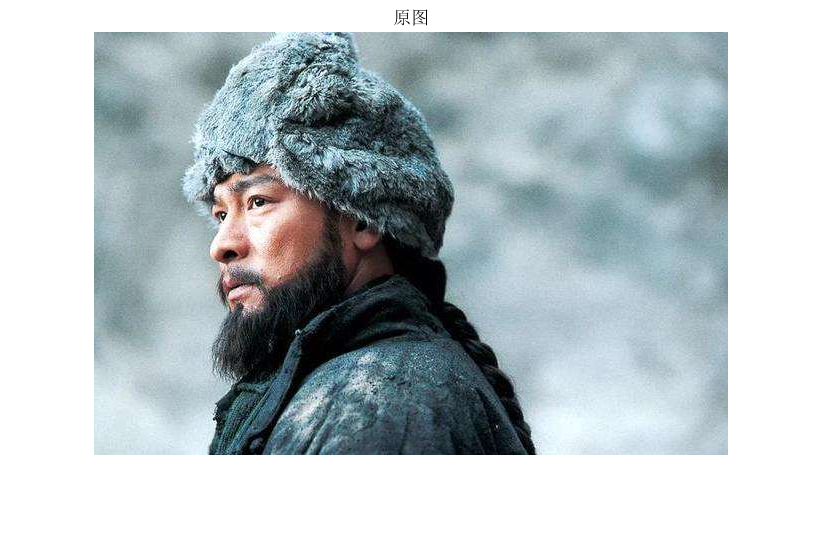

clc;clear;close all;%开局操作
image=imread("09-刘德华.jpg");
figure;
imshow(image);
title("原图");

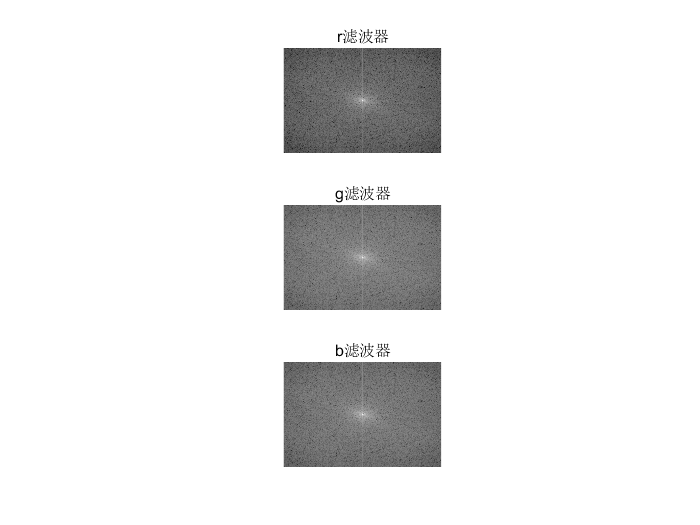

image_1=double(image);%创建副本

image_1(:,:,1)=fft2(image_1(:,:,1));%计算fft
image_1(:,:,2)=fft2(image_1(:,:,2));%计算fft
image_1(:,:,3)=fft2(image_1(:,:,3));%计算fft



figure;

imlvboqi=image_1(:,:,1);%顾名思义，这个是滤波器
subplot(3,1,1);

imlvboqi=mat2gray(log(abs(imlvboqi)));%转化幅度谱为目标函数
imlvboqi=fftshift(imlvboqi);
imshow(imlvboqi,'InitialMagnification','fit');


title("r滤波器");
imlvboqi=image_1(:,:,2);
subplot(3,1,2);

imlvboqi=mat2gray(log(abs(imlvboqi)));%转化幅度谱为目标函数
imlvboqi=fftshift(imlvboqi);
imshow(imlvboqi,'InitialMagnification','fit');


title("g滤波器");
imlvboqi=image_1(:,:,3);
subplot(3,1,3);

imlvboqi=mat2gray(log(abs(imlvboqi)));%转化幅度谱为目标函数
imlvboqi=fftshift(imlvboqi);
imshow(imlvboqi,'InitialMagnification','fit');

title("b滤波器");

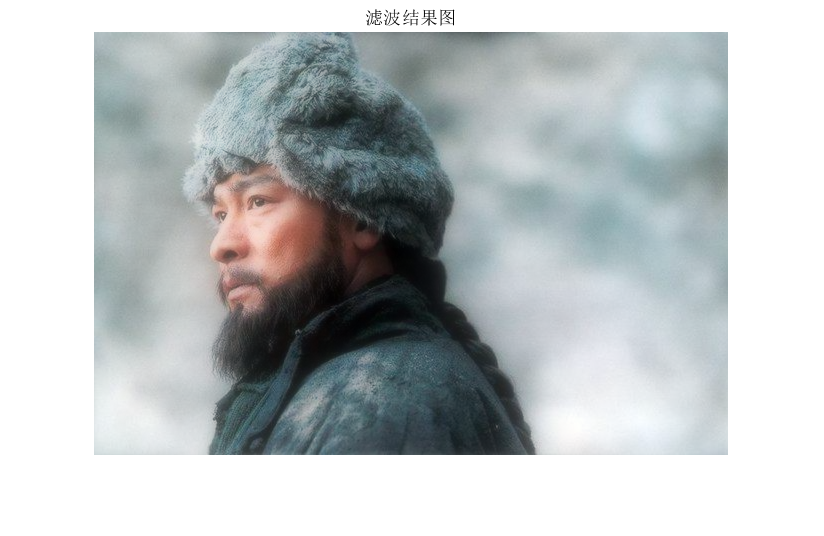




a=0.2;%指数因子，多番尝试下发现a=0.2时候与答案最接近
image_1(:,:,1)=image_1(:,:,1).*(abs(image_1(:,:,1))).^a;%计算滤波结果
image_1(:,:,2)=image_1(:,:,2).*(abs(image_1(:,:,2))).^a;
image_1(:,:,3)=image_1(:,:,3).*(abs(image_1(:,:,3))).^a;

image_1(:,:,1)=mat2gray(ifft2(image_1(:,:,1)));%计算ifft
image_1(:,:,2)=mat2gray(ifft2(image_1(:,:,2)));%计算ifft
image_1(:,:,3)=mat2gray(ifft2(image_1(:,:,3)));%计算ifft

figure;

imshow(real(image_1));%画出滤波结果图
title("滤波结果图");